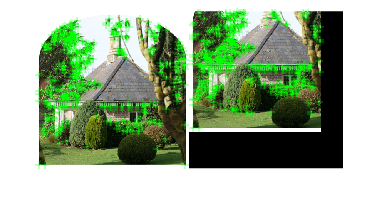

left = imread("leftoriginal.png");
right = imread("leftshifted.png");
corners_left = detectHarrisFeatures(im2gray(left));
corners_right = detectHarrisFeatures(im2gray(right));
figure;
combined = zeros(size(left));
combined = [combined combined];
combined(1:size(left,1),1:size(left,2),1:size(left,3)) = left;
combined(1:size(right,1),size(left,2):size(left,2)+size(right,2)-1,1:size(right,3)) = right;
combined = uint8(combined);
imshow(combined);
hold on;
quantity = 500;
strongest_left = corners_left.selectStrongest(quantity);
strongest_right = corners_right.selectStrongest(quantity);
strongest_left.Location = fliplr(strongest_left.Location);
strongest_right.Location = fliplr(strongest_right.Location);
plot(strongest_left.Location(:,2),strongest_left.Location(:,1),"g+");
plot(strongest_right.Location(:,2)+size(left,2),strongest_right.Location(:,1),"g+");

radius = 5;
offset_left = zeros(size(left)+[2*radius,2*radius,0]);
offset_left(radius+1:end-radius,radius+1:end-radius,:) = imgaussfilt(left,3);
offset_right = zeros(size(right)+[2*radius,2*radius,0]);
offset_right(radius+1:end-radius,radius+1:end-radius,:) = imgaussfilt(right,3);

minxy = uint32(strongest_right.Location);
maxxy = uint32(strongest_right.Location+2*radius);
descriptors_right = zeros(2*radius+1,2*radius+1,3,length(minxy));
for i=1:size(descriptors_right,4)
    descriptors_right(:,:,:,i) = offset_right(minxy(i,1):maxxy(i,1),minxy(i,2):maxxy(i,2),:);
end

selected_points = zeros(quantity,2);
selected_points(:,1) = randperm(quantity,size(selected_points,1))';
matched_points = zeros(size(selected_points));
matched_points(:,2) = 10^12;
remaining_selected = true(size(selected_points,1),1);
remaining_matched = true(size(matched_points,1),1);

for j=1:20
    for i=1:length(selected_points)
        if ~remaining_selected(i)
            continue
        end
        minxy = uint32(strongest_left.Location(selected_points(i,1),:));
        maxxy = uint32(strongest_left.Location(selected_points(i,1),:)+2*radius);
        descriptor_left = offset_left(minxy(1):maxxy(1),minxy(2):maxxy(2),:);
        sd = (descriptors_right(:,:,:,remaining_matched)-descriptor_left).^2;
        ssd = sum(sd,1:3);
        ssd = squeeze(ssd);
        [v,idx] = min(ssd);
        idx = find(remaining_matched==1,idx,"first");
        idx = idx(end);
        if v<matched_points(idx,2)
            if matched_points(idx,1)>0
                selected_points(matched_points(idx,1),2) = 0;
            end
            selected_points(i,2) = idx;
            matched_points(idx,1) = i;
            matched_points(idx,2) = v;
        end
    end
    remaining_selected = selected_points(:,2)==0;
    remaining_matched = matched_points(:,1)==0;
    sum(remaining_selected)
    if sum(remaining_selected)==0
        break
    end
end

ans = 168

ans = 112

ans = 90

ans = 77

ans = 68

ans = 61

ans = 60

ans = 56

ans = 51

ans = 46

ans = 41

ans = 35

ans = 31

ans = 26

ans = 22

ans = 18

ans = 17

ans = 14

ans = 11

ans = 8

old_selected_points = selected_points;
selected_points = selected_points(selected_points(:,2)~=0,:);

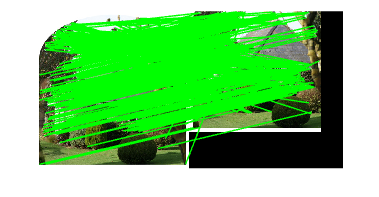

x1 = strongest_left.Location(selected_points(:,1),2);
y1 = strongest_left.Location(selected_points(:,1),1);
x2 = strongest_right.Location(selected_points(:,2),2)+size(left,2);
y2 = strongest_right.Location(selected_points(:,2),1);
figure;
imshow(combined);
hold on;
plot([x1,x2]',[y1,y2]',"g-");

slope_dev = 0.5;
length_dev = 0.5;
slopes = (y2-y1)./(x2-x1);
lengths = sqrt((y2-y1).^2.+(x2-x1).^2);
figure;
histogram(slopes)
m=mode(round(slopes,1));
s=slope_dev*std(slopes)

s = single
0.1899

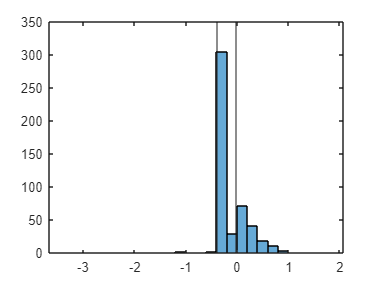

xline(m+s)
xline(m-s)

slope_inliers = (m-s)<slopes & slopes<(m+s);
figure;
histogram(lengths)
m=mode(round(lengths,-1))

m = single
410

s=length_dev*std(lengths)

s = single
45.5440

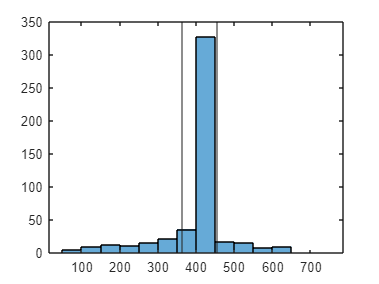

xline(m+s)
xline(m-s)

length_inliers = (m-s)<lengths & lengths<(m+s);
inliers = slope_inliers & length_inliers;
sum(inliers)

ans = 310

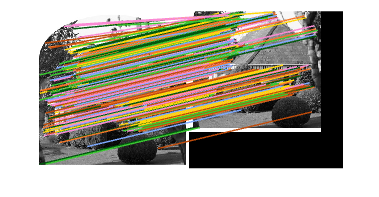

x1_filtered = strongest_left.Location(selected_points(inliers,1),2);
y1_filtered = strongest_left.Location(selected_points(inliers,1),1);
x2_filtered = strongest_right.Location(selected_points(inliers,2),2)+size(left,2);
y2_filtered = strongest_right.Location(selected_points(inliers,2),1);
figure;
imshow(im2gray(combined));
hold on;
plot([x1_filtered,x2_filtered]',[y1_filtered,y2_filtered]',"-");
colororder("meadow");